# PART 2

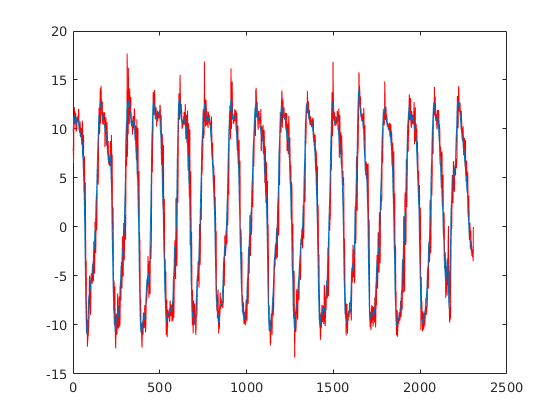


%% Prepare data and filter settings
% Set the window size. 
%%%%% You will need to change this! %%%%%
window_size = 10;

% Import the data we've generated. You can find this file on Canvas.
data = csvread('z_flip_data.csv');

% Separate the data:
% Raw signal
z_raw = data(:, 2);
% Time, converted to s
time = data(:, 1) ./ 1000;

% Quick sanity check to avoid improper window size settings
if window_size > length(z_raw)
    disp('Your window size is bigger than the whole dataset!')
	return;
end

% Create the array that will hold the filtered values
z_filtered = zeros(1, length(z_raw) - window_size + 1);

%% Run the moving average filter
% Like a real-time filter, this will be front-biased. That means it will
% take the average of the most recent n (window size) datapoints. 

% Loop through the data, gathering the averages
% i represents the front of the window (newest data in filter)
for f = window_size:length(z_raw)
    % Find the back of the window (oldest data in filter)
    b = f - window_size + 1;
    % We can also use b as the index for our filtered data    
	z_filtered(b) = mean(z_raw(b:f));
    % Within z_raw(b:f), there should always be n (window size) datapoints
end



%%%%% Your FFT, plotting, and other code goes here! %%%%%
%Run an FFT analysis
plot(z_raw, 'r')
hold on
plot(z_filtered)